# Sprawozdanie Lab3 

# AiR/KSS - Robotyka Kosmiczna - Paweł Mańka 


l1 = 0.6; % [m]
l2 = 0.5; % [m]
m1 = 2.5; % [kg]
m2 = 1.5; % [kg]

%przegub 1
q_p1 = 1;
dq_p1 = 0;
q_k1 = 3;
dq_k1 = 1;
Tk1 = 10;
Ta1 = 4;
Tb1 = 3;
dt1 = 0.01;
V1 = 0.06; 

[q1, dq1, ddq1] = Trajectory_Generation(q_p1, dq_p1, q_k1, dq_k1, Tk1, Ta1, Tb1, dt1,V1);
% plot_trajectory(q1, dq1, ddq1)

%przegub 2
q_p2 = 2;
dq_p2 = 0;
q_k2 = 0;
dq_k2 = -1;
Tk2 = 10;
Ta2 = 4;
Tb2 = 3;
dt2 = 0.01;
V2 = -0.1;

[q2, dq2, ddq2] = Trajectory_Generation(q_p2, dq_p2, q_k2, dq_k2, Tk2, Ta2, Tb2, dt2,V2);

dq1 = double(dq1);
q1 = double(q1);
ddq1 = double(ddq1);
q2 = double(q2);
dq2 = double(dq2);
ddq2 = double(ddq2);

q = [q1; q2];
dq = [dq1; dq2];


%model dynamiki:
i(1) = 0;
for i = 1:length(q1)
    M1 = 0;
    M2 = -m2*l1*l2*(dq(1, i) + (1/2)*dq(2, i)) * sin(q(2, i));
    M3 = 1/2*m2*l1*l2*dq(1, i)*sin(dq(2, i));
    M4 = 0;
    
    T1 = ((1/3)*m1+m2)*(l1^2) + ((1/3)*m2*(l2^2)) + (m2*l1*l2*cos(q(2, i)));
    T2 = ((1/3)*m2*(l2^2))+((1/2)*m2*l1*l2*cos(q(2, i)));
    T3 = ((1/3)*m2*(l2^2))+((1/2)*m2*l1*l2*cos(q(2, i)));
    T4 = ((1/3)*m2*(l2^2));
    
    M = [M1 M2;
        M3 M4];
    T = [T1 T2;
        T3 T4];
    u(:, i) = T*[ddq1(i); ddq2(i)] + M * [dq(1, i); dq(2, i)];
end 

time = (1:length(q))./100

time =     0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900    0.5000


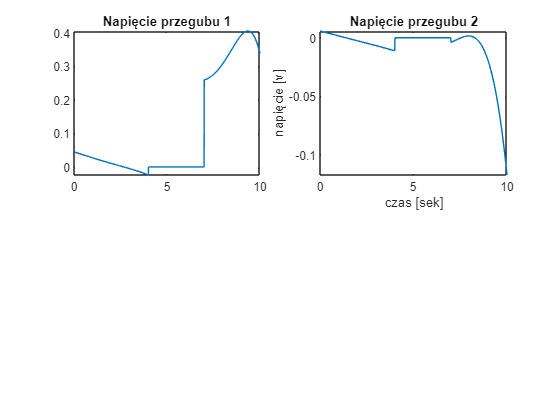

figure;
title("Sterowanie przegubami robota")
subplot(2, 2, 1)
plot(time,u(1, :))
title("Napięcie przegubu 1")

subplot(2, 2, 2)
plot(time,u(2, :))
title("Napięcie przegubu 2")
xlabel("czas [sek]")
ylabel("napięcie [v]")

%odwrocony model dynamiki
q0 = [1; 2];
dq0 = [0; 0];
l1 = 0.6; % [m]
l2 = 0.5; % [m]
m1 = 2.5; % [kg]
m2 = 1.5; % [kg]
u_in = double(u);
[q_check, dq_check] = rk4(u_in, q0, dq0, l1, l2, m1, m2);

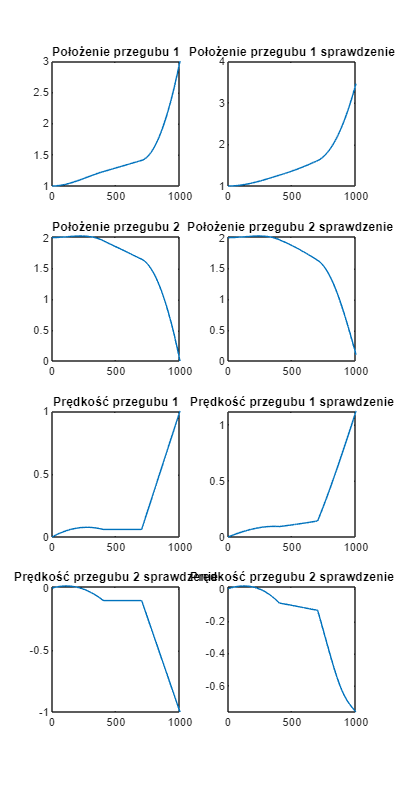

figure;
plot_lab_3_check(q, dq, q_check, dq_check)

function [q, dq] = rk4(u, q0, dq0, l1, l2, m1, m2)
    h = 0.01;
    time(1) = 0;
    q(:, 1) = q0;
    dq(:, 1) = dq0;

    
    % M 
    for i = 1:1:1000
        M1 = 0;
        M2 = -m2*l1*l2*(dq(1, i) + (1/2)*dq(2, i)) * sin(q(2, i));
        M3 = 1/2*m2*l1*l2*dq(1, i)*sin(dq(2, i));
        M4 = 0;
        
        T1 = ((1/3)*m1+m2)*(l1^2) + ((1/3)*m2*(l2^2)) + (m2*l1*l2*cos(q(2, i)));
        T2 = ((1/3)*m2*(l2^2))+((1/2)*m2*l1*l2*cos(q(2, i)));
        T3 = ((1/3)*m2*(l2^2))+((1/2)*m2*l1*l2*cos(q(2, i)));
        T4 = ((1/3)*m2*(l2^2));
        
        M = [M1 M2;
            M3 M4];
        T = [T1 T2;
            T3 T4];

        k11 = h .* dq(:, i);
        k12 = h .* inv(T) * (u(:, i) - M*dq(:, i));
        k21 = h .* (dq(:, i) + k11/2);
        k22 = h .* (inv(T) * (u(:, i) - M*dq(:, i)) + k12/2);
        k31 = h .* (dq(:, i) + k21/2);
        k32 = h .* (inv(T) * (u(:, i) - M*dq(:, i)) + k22/2);
        k41 = h .* (dq(:, i)+ k31);
        k42 = h .* (inv(T) * (u(:, i) - M*dq(:, i)) + k32);

        k1 = (1/6) * (k11 + 2*k21 + 2*k31 + k41);
        k2 = (1/6) * (k21 + 2*k22 + 2*k32 + k42);

        q(:, i + 1) = q(:,i) + k1;
        dq(:, i + 1) = dq(:,i) + k2;

    end
end

function plot_lab_3_check(q,dq, q_check, dq_check)
    f = figure;
    f.Position = [100 100 2000 4000];
    
    subplot(4, 2, 1)
    plot(q(1,:))
    title("Położenie przegubu 1")

    subplot(4, 2, 2)
    plot(q_check(1,:))
    title("Położenie przegubu 1 sprawdzenie")

    subplot(4, 2, 3)
    plot(q(2,:))
    title("Położenie przegubu 2")

    subplot(4, 2, 4)
    plot(q_check(2,:))
    title("Położenie przegubu 2 sprawdzenie ")

    subplot(4, 2, 5)
    plot(dq(1,:))
    title("Prędkość przegubu 1")

    subplot(4, 2, 6)
    plot(dq_check(1,:))
    title("Prędkość przegubu 1 sprawdzenie")

    subplot(4, 2, 7)
    plot(dq(2,:))
    title("Prędkość przegubu 2 sprawdzenie")

    subplot(4, 2, 8)
    plot(dq_check(2,:))
    title("Prędkość przegubu 2 sprawdzenie")

end 